# Simple Geometry FEA

## Intro

clear
clc
clf

set(0,'DefaultAxesFontSize',15,'defaultaxeslinewidth',2,...
    'defaultlinelinewidth',5,'defaultpatchlinewidth',1.5)

## Import the Geometry

### Define Material Geometry

The geometry is comprised of a conductive mesh within a finite volume defined by a cube. This geometry for the air is initialized and stored as gmAir. This is done first so that the geometry of the conductive mesh can fit inside the volume when it is then centered on the mesh. 

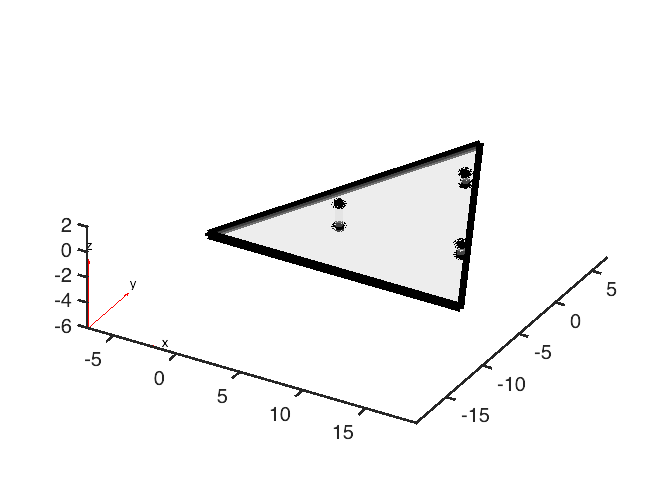

% Select the model and assign to gmModel

%Circle   = importGeometry('Basic 35mm Circle.stl');
%Circle   = importGeometry('Basic 30x30mm Square.stl');
%Circle= importGeometry('Basic 42x42mm Triangle.stl');
Circle = importGeometry('Triangle 3 Electrode (3).stl');
%Star     = importGeometry('Basic Star.stl');
pdegplot(Circle,'FaceAlpha',0.3);


%Electrode
% gmCylinder = multicylinder(.2,1)
% pdegplot(gmCylinder,'FaceAlpha',0.3);


### Define Fluid Volume

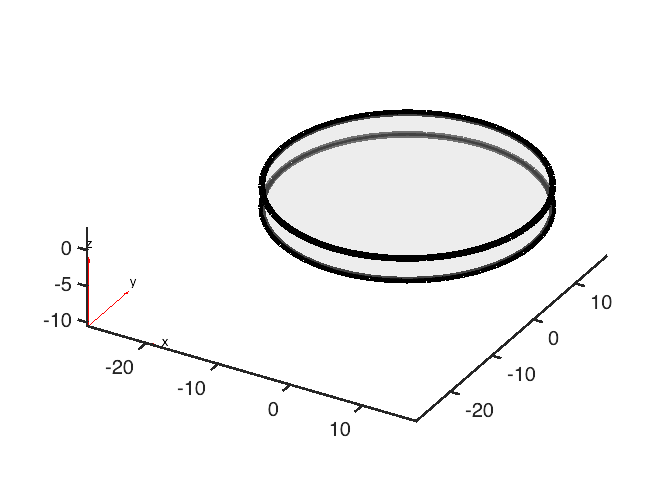

%First plot geometry and adjust the the volume of the container of fluid then incorporate the
%geometry
gmFluid = multicylinder(17.5,3);
pdegplot(gmFluid,'FaceAlpha',0.3);

### Combine Both Geometries

Circle.translate([-7,7,.005]);
gmModel = addCell(gmFluid,Circle);
gmModel = scale(gmModel,.001); %scaled from mm to m

### Assign The Geomtery to the Model

The defined geometry becomes set to the model handle. The model is created and defined as Estat_model which is also an N # of equation elliptic model. 

%N = 3
Estat_model = createpde;
%Estat_model = createpde("electromagnetic","electrostatic");
Estat_model.Geometry = gmModel;

### Initial Plot of Loaded Geometries

Change the FaceAlpa input in pdegplot to better view the face and edge lables of the geometry.

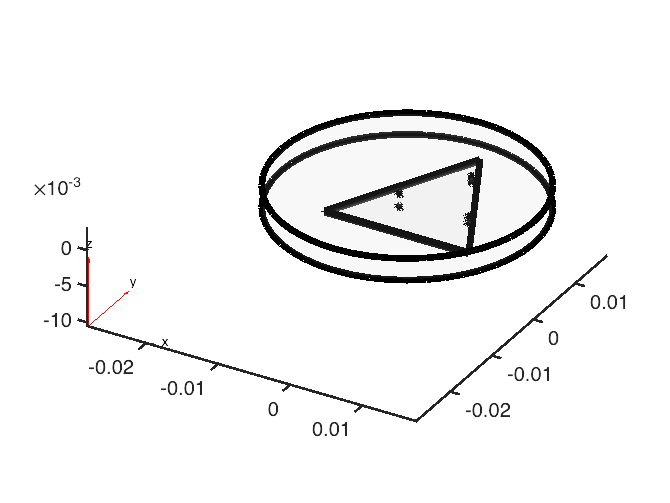

pdegplot(Estat_model,'FaceAlpha',0.1);

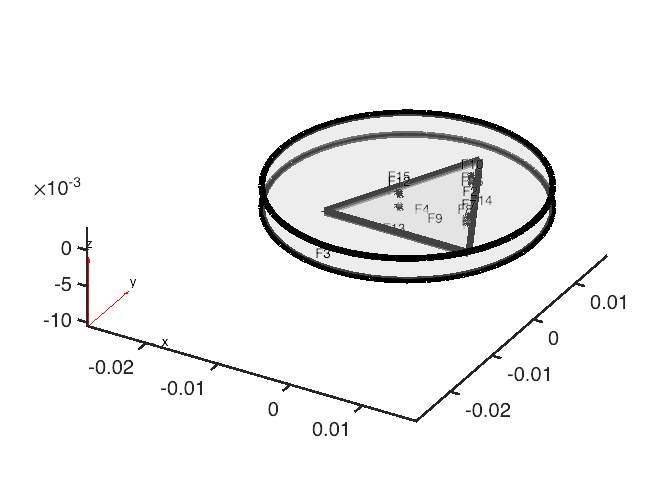


pdegplot(Estat_model,'FaceLabels','on','FaceAlpha',.3);

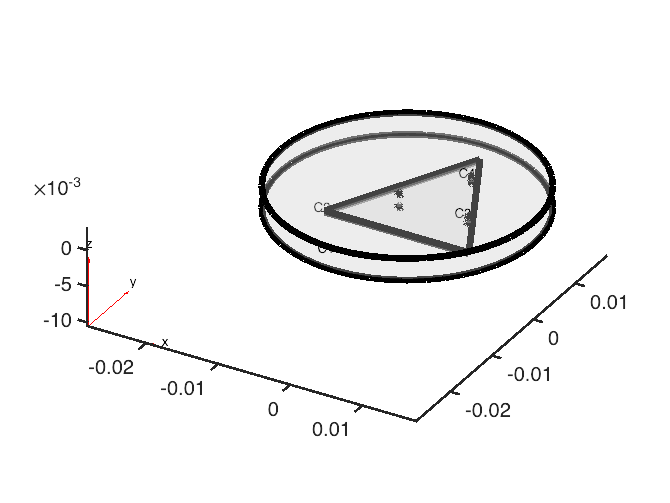


pdegplot(Estat_model,'CellLabels','on','FaceAlpha',.3);

## Create the Mesh

From this we can generate a mesh where the fineness is defined by Hmin value, set at .35 for the lowest fideltiy model and Hmax at 1.5 for high fidelity models. The mesh then gets assigned to the Estat_model.

mesh = generateMesh(Estat_model, 'Hmax',.001);

%elemsBushing = findElements(Estat_model.Mesh,"Region","Cell",2);


The mesh can then be visualized for completeness and accuracy

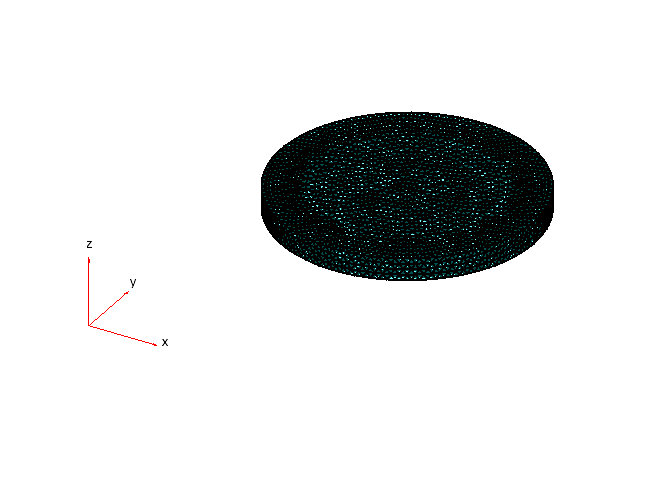

pdemesh(Estat_model,'FaceAlpha',.3)

The sizing of the mesh and geometery can be calculated by measuring the max distance between nodes in each direction. This value should be consistent with the dimensions of the geometry that was uploaded. 

% Measuring the dimesions of the mesh
xLength = max(Estat_model.Mesh.Nodes(1,:)) - min(Estat_model.Mesh.Nodes(1,:))

xLength = 0.0350

yLength = max(Estat_model.Mesh.Nodes(2,:)) - min(Estat_model.Mesh.Nodes(2,:))

yLength = 0.0350

zLength = max(Estat_model.Mesh.Nodes(3,:)) - min(Estat_model.Mesh.Nodes(3,:))

zLength = 0.0030


%Splitting components


## Parameters of the PDE & Governing Equations

### Parameters

These parameters are defined to represent the characteristics of the electrolyte solution and the material properties

global Dc Da zc za F muc mua ep_0 ep_r
%Electrolyte
% Cation diffusion coefficient m2 s−1 (Sodium Na+)
Dc = 1.33E-4;
% Anion diffusion coefficient  m2 s−1 (Chloride Cl-)
Da = 2.03E-4;
% Cation Valence
zc = 1;
% Anion Valence
za = -1;
% Bound Charges
matval = nan;
% Temperature K
Temp = nan;
% Gas Constant J mol−1 K−1
Gas_Cons = nan;
% Faraday Constant C mol−1
F = 96485;
% Cation Mobility m2 s−1 V−1
muc = 4.98E-8;
% Anion Mobility m2 s−1 V−1
mua = 6.88E-8;
% Vacuum Permitivity AsV−1 m−1
ep_0 = 8.854E10-12;
% Relative Permitivity
ep_r= 100;
%fluid velocity
v =0;
%Relative Permitivity
epsilon = 5;
%Relative Permeability 
mu = 1;
%Conductivity
sigma = .002;

### Establish Time Domain of Simulation 

tlist = linspace(0,2,10);

### Define Conditions of the Numerical Simulation

Define conditions for the ion concentrations of the bulk material and the fluid medium. 

- Concentration of bound anionic groups

- Concentration of free cationic and anionic groups 

- Boundary conditions for the concentration near surfaces 

- Potential Values for electrodes

cc_i = 10;
ca_i = 10;

Electrode_Face = 2;
Electrode_Face_Voltage = .4;

% initial_conditions = [cc_i; ca_i; Electrode_Face_Voltage];
% 
% setInitialConditions(Estat_model,initial_conditions)
% %applyBoundaryCondition(Estat_model,'dirichlet','face',Electrode_Face,'u',[0,0,initial_conditions(3)]);


### Define Governing Equations

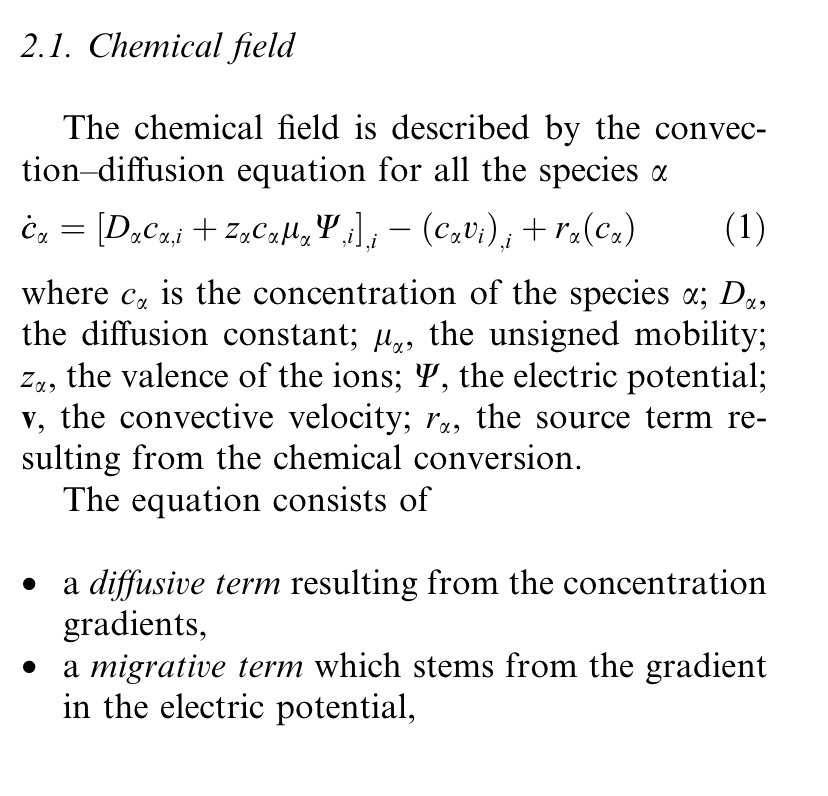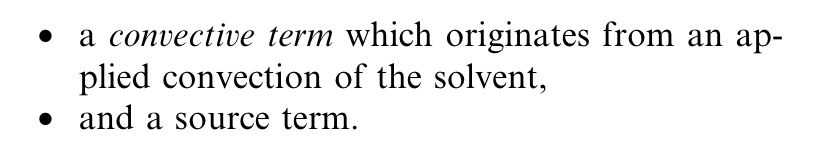

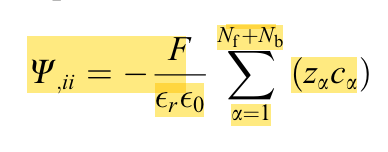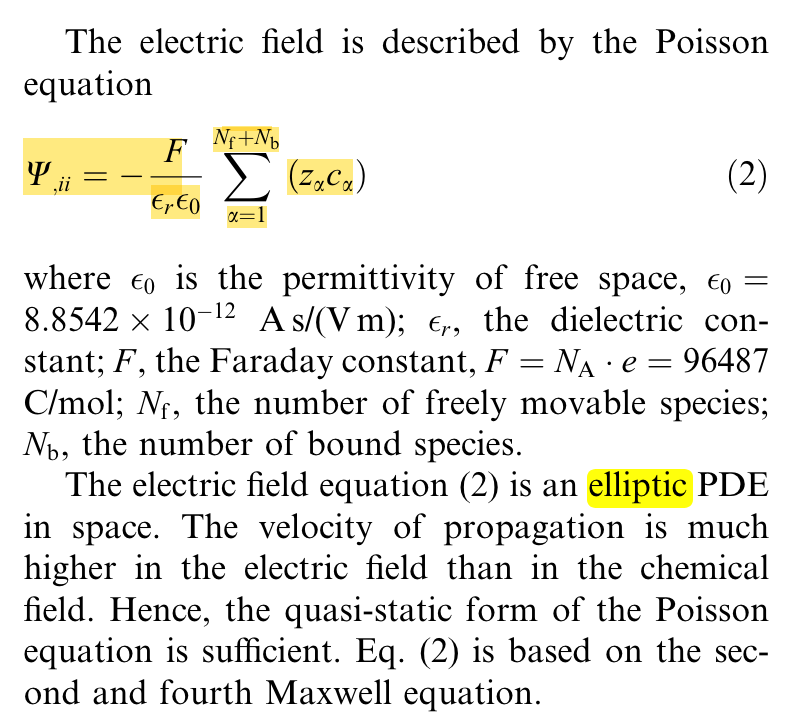

The governing equations are defined as above and implimented below. Both are elliptic equations that (1) describe the chemical field and (2) describe the electrical field. They are coupled non-linear equations that are dependant on space (2) and time (1).

Considering the coupled chemo-electric field only, for the (Nf þ Nb) concentration unknowns and for the unknown electric potential, the (Nf þ Nb) convection–diffusion equations and the Poisson equation are solved simultaneously (Wallmpsberger et a.).

% % Defining rate of change of ion concentration

% f(1,:) = -(F/(ep_r*ep_0))*(zc*cc+za*ca);
% f(2,:) = dcdt(cc, ca, cab, V, v)+[ca, cc, cab];

% f(2,:) = (Dc*cc+zc*cc*muc*V)-(cc*v)+(rc*cc);
% f(3,:) = (Da*cc+za*cc*mua*V)-(ca*v)+(ra*ca);

% d/dx (D_n*dn/dx) - mu_n*(dn/dx*dpsi/dx + n*q/eps*(n-p)) = dcc/dt
% d/dx (D_p*dp/dx) + mu_p*(dp/dx*dpsi/dx + p*q/eps*(n-p)) = dca/dt

#### Chemical Field

Chem_Field = createpde(2);

#### Apply Geometry

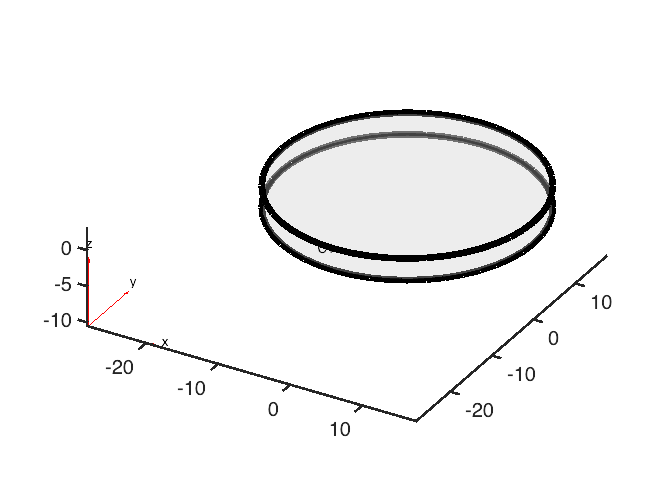

gmFluid = multicylinder(17.5,3);
% geometryFromMesh(Chem_Field,F_mesh,F_nodes);
Chem_Field.Geometry = gmFluid;
pdegplot(Chem_Field,'CellLabels','on','FaceAlpha',.3);


generateMesh(Chem_Field,"Hmax",1.0)

ans =   FEMesh with properties:

             Nodes: [3×35248 double]
          Elements: [10×22497 double]
    MaxElementSize: 1
    MinElementSize: 0.5000
     MeshGradation: 1.5000
    GeometricOrder: 'quadratic'


#### Specify Coefficients as Model Definition

V = 5;
[acc, aca] = aco(V);

m = 0;
d = 0

d = 0

c = acc %[acc;aca];

c = -1.3325e-04

a = 0

a = 0

f = [0;0];
% specifyCoefficients(Estat_model,'m',m,'d',d,'c',c,'a',a,'f',f);
specifyCoefficients(Chem_Field,'m',m,'d',d,'c',c,'a',a,'f',f);

#### **Specify Boundary Conditions**

## Material Properties  

The materials of interest are the electrolyte medium or culture medium, scaffold polymer material and dopant, working electrode material.

First make necessary unit conversions to match the units expected from matlab

%% Conversions

Define permeability and permittivity values as perscribed for the fluid volume.

%%Vacuum
% Estat_model.VacuumPermeability = 1.2566370614E-6;
% Estat_model.VacuumPermittivity = 8.8541878128E-12;

%%Culture Medium
%electromagneticProperties(Estat_model,"Cell",1,"RelativePermittivity",1);

% %%ITO
% electromagneticProperties(emagmodel,"RelativePermittivity",2.25, ...
%                                     "Face", ITO_Face)

% %%Electrodes
% electromagneticProperties(emagmodel,"RelativePermittivity",2.25, ...
%                                     "Face", ITO_Face)

%Scaffold
%electromagneticProperties(Estat_model,"Cell",1,"RelativePermittivity",1)

%electromagneticProperties(Estat_model,"RelativePermittivity",epsilon,"RelativePermeability",mu,"Conductivity",sigma)

## Boundary Conditions

In the pHEMA paper the conductivity of these scaffolds was tested using a custome ITO dual electrode setup. The boundary conditions of the faces that make contact with this electrode setup are set to be constant voltages.

%electromagneticBC(Estat_model,'Face',Electrode_Face,'Voltage',Electrode_Face_Voltage)
% applyBoundaryCondition(Estat_model,'dirichlet', ...
%                              'Face',[6,12],'u',5 ...);
% applyBoundaryCondition(Estat_model,'dirichlet', ...
%                              'Face',[1,2,3],'u',0);
% applyBoundaryCondition(Estat_model,'dirichlet', ...
%                              'Face',[5,7,8],'u',0);


## Charge Density

%Scaffold
%electromagneticSource(Estat_model,"ChargeDensity",5E-3);

%% BC ITO
%electromagneticBC(Estat_model,"Voltage",.008,"Face",5)
%BC Scaffold
%electromagneticBC(Electrodep_model,"Voltage",0,"Face",3:6)
%BC Working
%BC Counter


## Solving the Model

R_chem = solvepde(Chem_Field);


emagmodel = Estat_model;
R = solvepde(emagmodel);

## Visualizing Model Results

model = emagmodel;

### Electric Field Flow Data Plot

Plot of the electric field and distribuiton throughout the geometery. Be sure to adjust opacity of the plot to see features.

% R_results = results.NodalSolution;S_mesh = findElements(model.Mesh,"Region","Cell",Scaffold_Cell);
% F_mesh = findElements(model.Mesh,"Region","Cell",Fluid_Cell);
% CE_mesh = findElements(model.Mesh,"Region","Cell",Electrode_Cell);
% WE_mesh = findElements(model.Mesh,"Region","Cell",WE_Cell);
% RE_mesh = findElements(model.Mesh,"Region","Cell",RE_Cell);
S_mesh = findElements(model.Mesh,"Region","Cell",2);

pdeplot3D(model.Mesh.Nodes, ...
          model.Mesh.Elements(:,S_mesh),"ColorMapData",R.NodalSolution,"FaceAlpha", .5)
title('Electric Field [V]')
xlabel('x')
ylabel('y')
zlabel('z')


### Plot of Electric Flux Density 

pdeplot(emagmodel,"FlowData",[R.ElectricFluxDensity.Dx ...
    R.ElectricFluxDensity.Dy ...
    R.ElectricFluxDensity.Dz],'Mesh','on',"FaceAlpha", .5)
title('Flux Density')
xlabel('x')
ylabel('y')
zlabel('z')

### Plot of Electric Potential 

pdeplot3D(model,"ColorMapData",R.ElectricPotential)
title('Electric Potential [V]')
% 
% Emag = sqrt(R.ElectricField.Ex.^2 + ...
%     R.ElectricField.Ey.^2 + ...
%     R.ElectricField.Ez.^2);
% pdeplot3D(model.Mesh.Nodes, ...
%     model.Mesh.Elements(:,elemsBushing), ...
%     "ColorMapData",Emag);

axis equal
xlabel('x')
ylabel('y')
zlabel('z')

## Function Defs

function [dcc, dca, dcab] = dcdt(cc, ca, cab, V, v)
dcc = (Dc*cc+zc*cc*muc*V)-(cc*v)+(rc*cc);
dca = (Da*cc+za*cc*mua*V)-(ca*v)+(ra*ca);
dcab = (Dcab*cab+zab*cc*muab*V)-(cab*v)+(rab*cab);
end

function [acc, aca] = aco(V)
global zc za muc mua Da Dc
acc = -Dc - zc*muc*V;
aca = -Da - za*mua*V;
end


function fc = fco(ac)
global zc za F ep_0 ep_r
fcv = -(F/(ep_r*ep_0))*(zc*state.u(1,:)+za*state.u(2,:));
fc = [zeros(1,length(fcv));zeros(1,length(fcv));fcv];
end